**Homework #2**

**1) A little introductory brain teaser. Which is more probable when rolling 2 six-sided dice: rolling snake eyes (two ones) or rolling sevens (dice sum to seven)? What is the ratio of the probabilities?**

From lecture we know that the probablilty of rolling two ones is 1/36. 

While if you were to roll the dice to sum up seven there would be: 

1   2   3   4   5   6            12 possible ways, each

6   5   4   3   2   1           having 1/36 of a chance. 

(1/36)+(1/36)+(1/36)+(1/36)+(1/36)+(1/36) = 6/36 = 1/6 chance. Therefore it is more probable to roll 2 six-sided dice to sum to seven then get two ones. 

**2) Following what we did in class show how to use the convolution operator to determine the probability of the sum of 2 six sided dice. Do both analytically (math & counting) and numerically (computer program). Beware the *****implicit***** definition of the values (x-axis on histogram).**


$$\begin{array}{l}
X\;\mathrm{and}\;Y\;\mathrm{are}\;\mathrm{two}\;\mathrm{independent}\;\mathrm{discrete}\;\mathrm{random}\;\mathrm{variables}\;\mathrm{with}\;\mathrm{distribution}\;\mathrm{functions}\;m_1 \left(x\right)\;\mathrm{and}\;m_2 \left(x\right)\ldotp Z=X+Y,Z=m_3 \left(x\right)\\
Z\;\mathrm{also}\;\mathrm{talkes}\;\mathrm{the}\;\mathrm{value}\;\mathrm{of}\;z,z\;\mathrm{being}\;\mathrm{an}\;\mathrm{arbitrary}\;\mathrm{integer}\ldotp \mathrm{Consider}\;X=k,\mathrm{then}\;Z=z\;\;\mathrm{if}\;\mathrm{and}\;\mathrm{only}\;\mathrm{if}\;Y=z-k,\\
\left(X=k\right)\;\mathrm{and}\;\left(Y=z-k\right)\\
P\left(Z=z\right)=\sum_{k=-\infty }^{\infty } P\left(X=k\right)\cdot P\left(Y=z-k\right)\\
m_3 \left(x\right)=\sum_k m_1 \left(k\right)\cdot m_2 \left(j-k\right),j=\mathrm{integer}\ldotp \;\\
S_n =X_1 +X_2 +\ldotp \ldotp \ldotp +X_n \\
S_n =S_{n-1} +X_n \\
m=\left\lbrack \begin{array}{cccccc}
1 & 2 & 3 & 4 & 5 & 6\\
\frac{1}{6} & \frac{1}{6} & \frac{1}{6} & \frac{1}{6} & \frac{1}{6} & \frac{1}{6}
\end{array}\right\rbrack \\
P\left(S_2 =2\right)=m\left(1\right)m\left(1\right)=\left(\frac{1}{6}\right)\left(\frac{1}{6}\right)=\frac{1}{36}\\
P\left(S_2 =3\right)=m\left(1\right)m\left(2\right)+m\left(2\right)m\left(1\right)=\left(\frac{1}{6}\right)\left(\frac{1}{\left.6\right)}\right)+\left(\frac{1}{6}\right)\left(\frac{1}{6}\right)=\frac{2}{36}\\
P\left(S_2 =4\right)=m\left(1\right)m\left(3\right)+m\left(2\right)m\left(2\right)+m\left(3\right)m\left(1\right)=\left(\frac{1}{6}\right)\left(\frac{1}{\left.6\right)}\right)+\left(\frac{1}{6}\right)\left(\frac{1}{6}\right)+\left(\frac{1}{6}\right)\left(\frac{1}{6}\right)=\frac{3}{36}\\
P\left(S_2 =5\right)=\frac{4}{36}\\
P\left(S_2 =6\right)=\frac{5}{36}\\
P\left(S_2 =7\right)=\frac{6}{36}\\
P\left(S_2 =8\right)=\frac{5}{36}\\
P\left(S_2 =9\right)=\frac{4}{36}\\
P\left(S_2 =10\right)=\frac{3}{36}\\
P\left(S_2 =11\right)=\frac{2}{36}\\
P\left(S_2 =12\right)=\frac{1}{36}
\end{array}$$


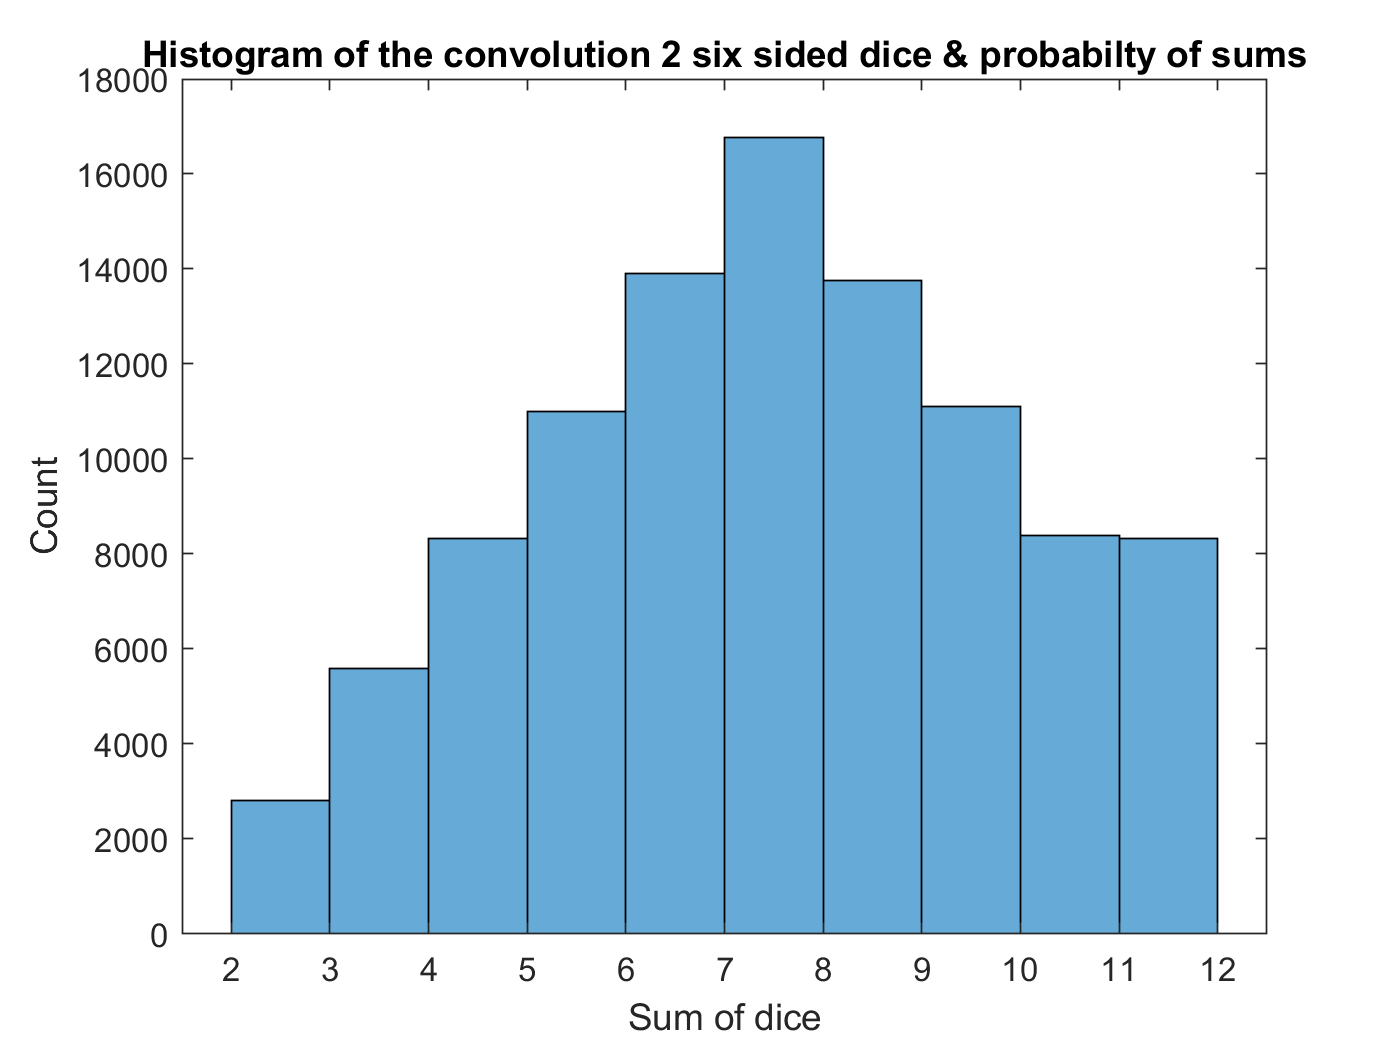

clear;close all;clc;
%Defining Parameters
NumDice=2;
NumFace=6;
NumRoll= 100000;

%rolls and the sums
AllRoll=randi(NumFace,NumRoll,NumDice);
SumRoll=sum(AllRoll,2);

%Bins and histogram
Bins=(NumDice:NumFace*NumDice)';
histogram(SumRoll,Bins);
title('Histogram of the convolution 2 six sided dice & probabilty of sums');
xlabel('Sum of dice');
ylabel('Count');

**3) Calculate the mean and the variance of the distribution in problem 2. Hint: this is surprisingly tricky, make sure your result makes sense.**

As discussed in class we know that the sum of the probablites equals one, and we found the mean by stating, $\mathrm{mean}=\Sigma x_{\mathrm{prob}} \;;\mathrm{while}\;\mathrm{it}\;\mathrm{should}\;\mathrm{be}\;\mathrm{over}\;\mathrm{the}\;\mathrm{sum}\;\mathrm{of}\;\mathrm{probabilites}\;\mathrm{but}\;\mathrm{that}\;\mathrm{is}\;\mathrm{one}\ldotp \;$

mean = 7;

While variance is the distance from the mean or the sigma squared, 


$$\mathrm{variance}=\sigma^2 =\Sigma {\left(x-m\right)}^2 \;\mathrm{prob}={\left(12-7\right)}^2 \cdot \frac{1}{36}=\frac{25}{36}$$


**4) Repeat 2, and graph the average of 10 dice. Is this is a Gaussian distribution? Explain in depth.**

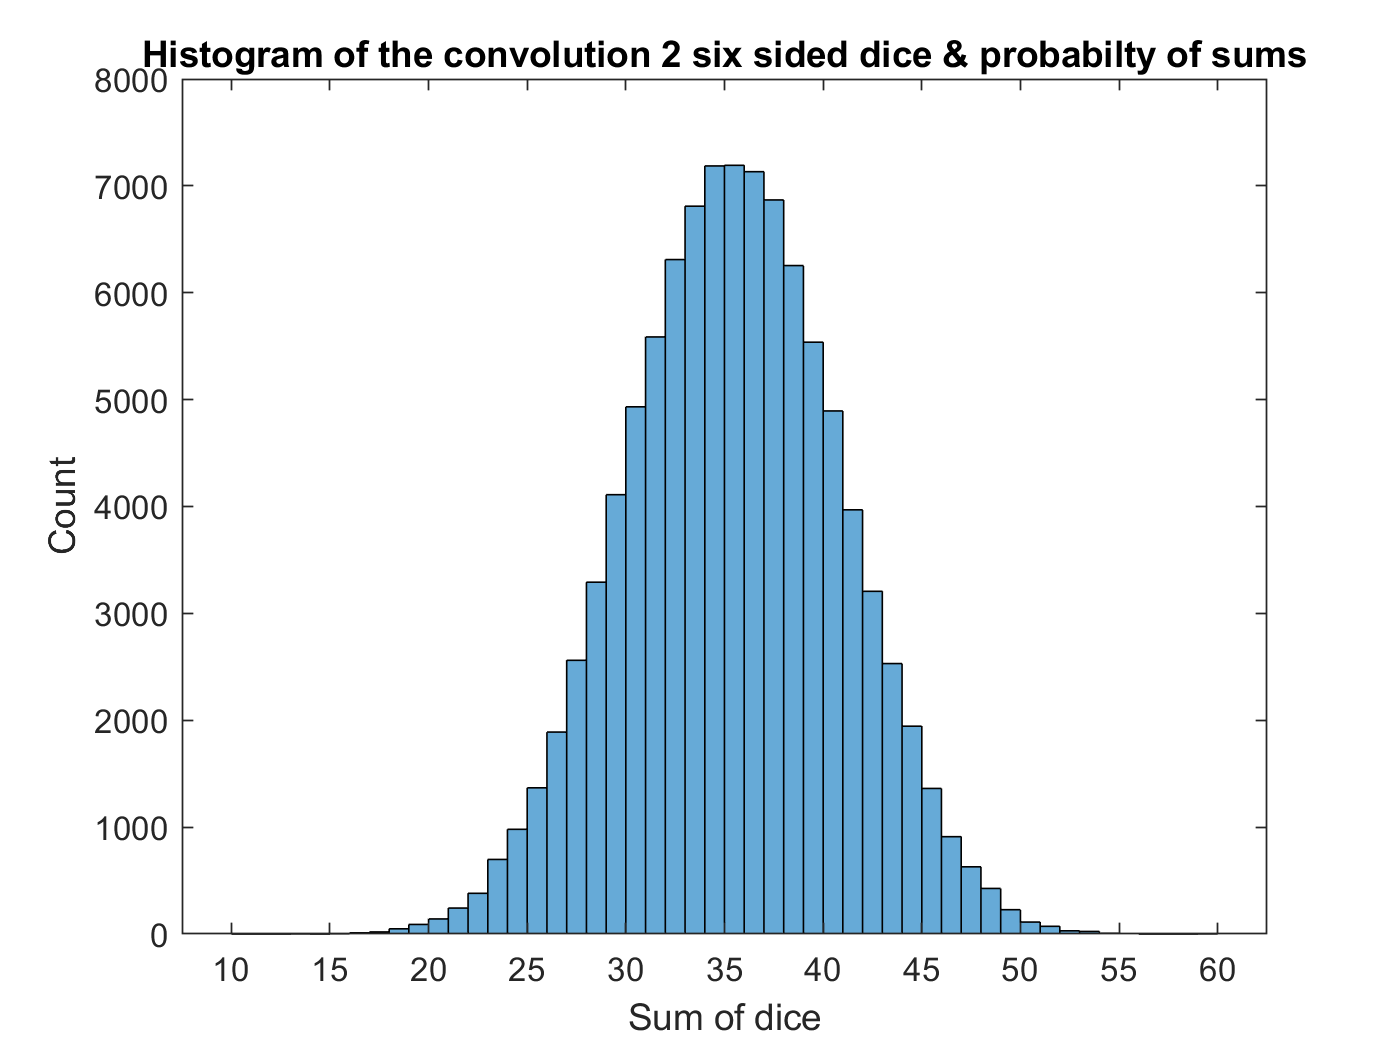


%Defining Parameters
NumDice=10;
NumFace=6;
NumRoll= 100000;

%rolls and the sums
AllRoll=randi(NumFace,NumRoll,NumDice);
SumRoll=sum(AllRoll,2);

%Bins and histogram
Bins=(NumDice:NumFace*NumDice)';
histogram(SumRoll,Bins);
title('Histogram of the convolution 2 six sided dice & probabilty of sums');
xlabel('Sum of dice');
ylabel('Count');

Yes we can clearly see that this is a Gaussian distribution because the distribution is continuous and bell curved. This follows the Central Limit Thm. where most distributions, when summed or average over enough trials will converge to a Gaussion probabilty function. 

**5) Show that the sum and average of an initially Gaussian distribution is also a Guassian (can be analytic or numerical). How does the standard deviation of the resulting sum or average Guassian change? This is a *****hugely***** important result. Explore what this means for integrating a signal over time.**

We know that each trial should be independent of each other, and doing them an infinite amount of times as said previously in number 4, if there are enough trials most distributions will converge to Guassian, starting off as a Guassian will change nothing, depending on if you add more trials as well as more components is what will change your standard deviation, sum and average. Just as for number 2, we only had two dice, and increased to 10, we saw that then sum, and average and variance increased, if we had just increased the number of trials and not number of dice I am sure that nothing would have changed. 